# Climate Proxies - Practical 2

This week's practical is focused on marine organic geochemistry, specifically the alkenone-based Uk'37 and GDGT-based TEX86 indices for SST. 

The definitions of these are:

     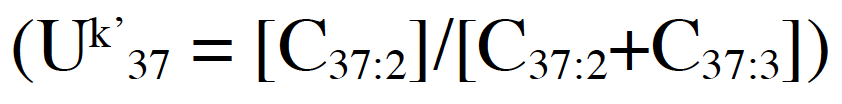

and

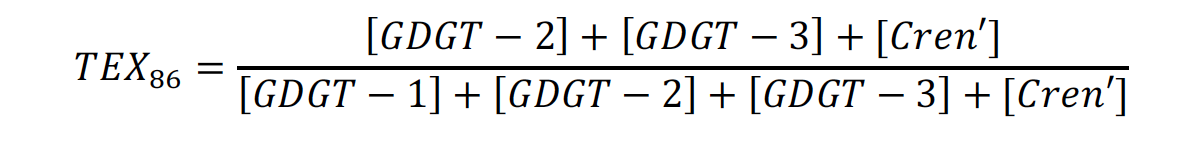

## Question 1 - Uk'37 

*Use the Muller et al., 1998 core top calibration and the South China Sea Uk'37 indices to reconstruct SSTs.*

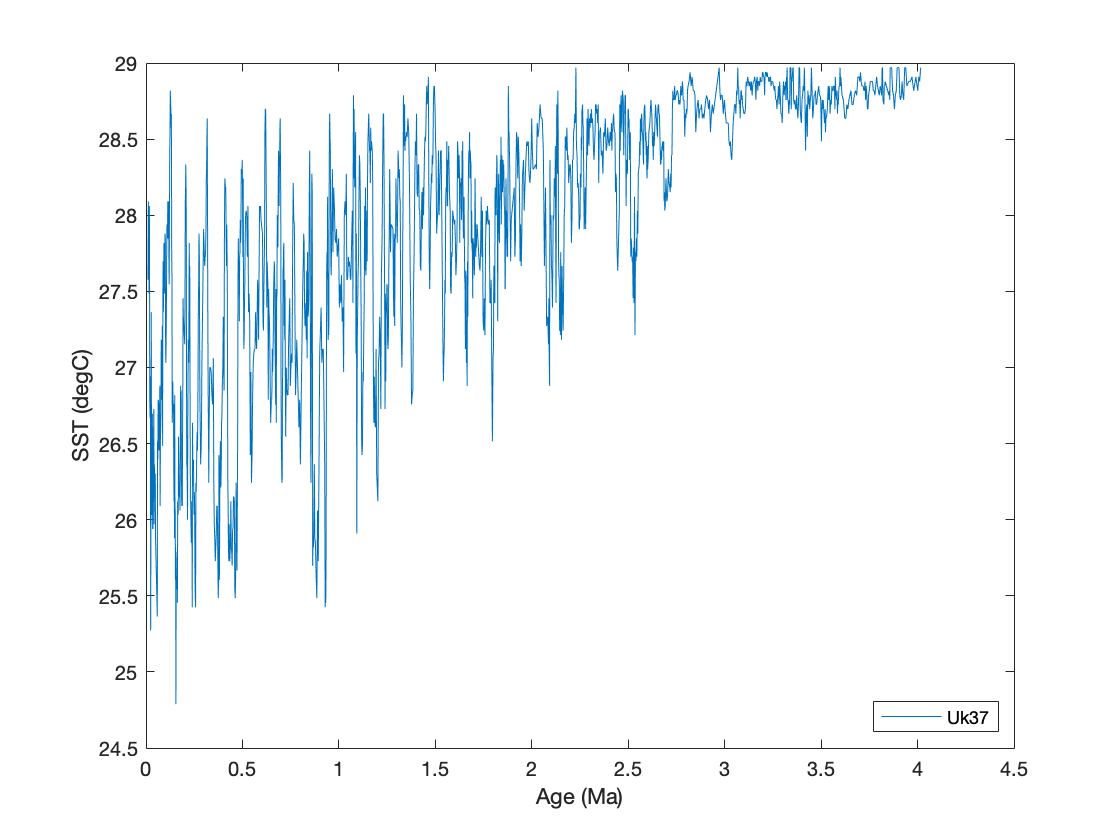

%Import SCS Uk'37 info
load("SCS_Li.mat");

%Use Muller et al. 1998's core top calibration (Uk'37 = 0.033SST + 0.044)
SCS_Li.SST = (SCS_Li.uk37-0.044)./0.033;

%Plot SST agains Age
figure(1)
plot(SCS_Li.age,SCS_Li.SST)
xlabel('Age (Ma)')
ylabel('SST (degC)')
legend('Uk37','location','southeast')

*What is the range of the Uk'37 SST estimates?*

%Find the maximum and minimum SST temperatures from the Uk'37
%reconstruction and print
max_uk37 = max(SCS_Li.SST);
min_uk37 = min(SCS_Li.SST);
fprintf(['The maximum and minimum SST values predicted by the Uk37 reconstruction...' ...
    ' are %.2f degrees C and %.2f degrees C respectively'],max_uk37,min_uk37)

The maximum and minimum SST values predicted by the Uk37 reconstruction... are 28.97 degrees C and 24.79 degrees C respectively

*What do you notice about the variability before and after 2.5Ma?*

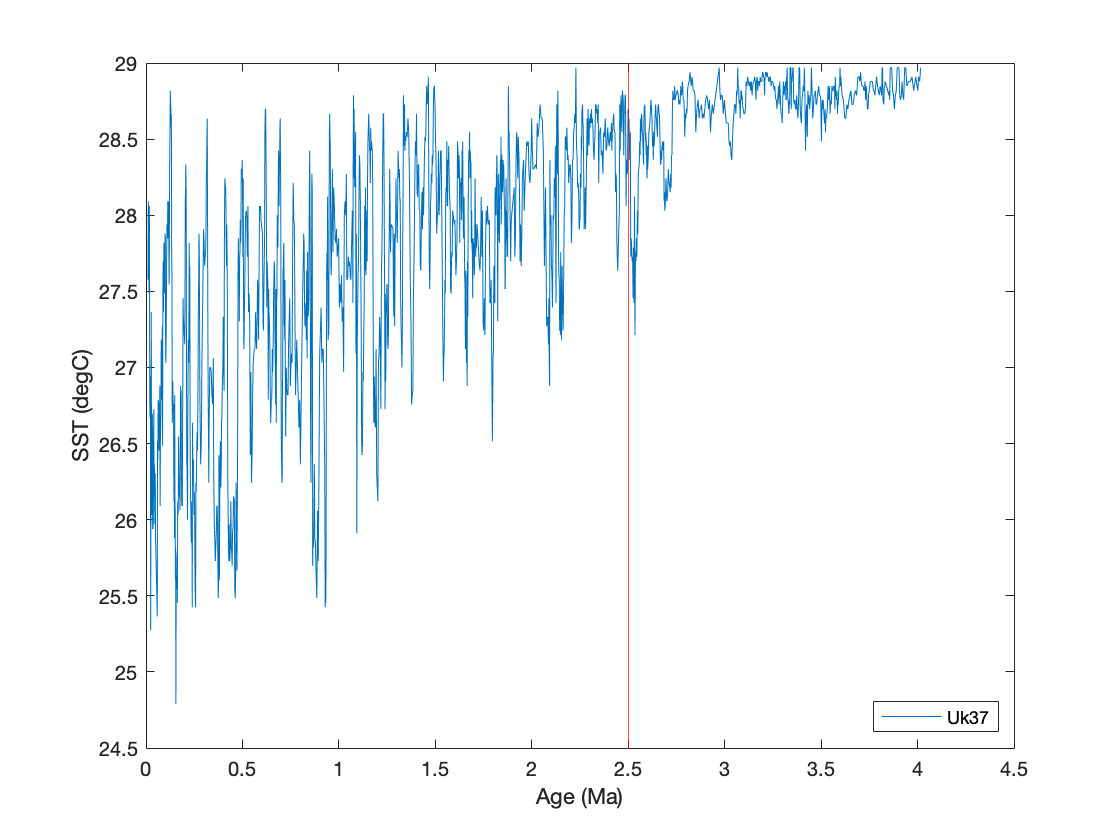

figure(2)
plot(SCS_Li.age,SCS_Li.SST)
xline(2.5,'r')
xlabel('Age (Ma)')
ylabel('SST (degC)')
legend('Uk37','location','southeast')

Before (earlier than) 2.5Ma, there is much lower variability than after 2.5Ma. The variability grows throughout the whole record.

*What might be the reason for this?*

The maximum possible reconstructed temperature using this Uk'37 reconstruction is 28.97 degrees C (corresponding to a Uk'37 value of 1). This means that even if the South China Sea had had a greater SST than 28.97 degrees C, the reconstruction will present it as having been 28.97 degrees, and therefore fluctuations across this boundary would not be represented well, instead being represented with only small fluctuations, therefore artificially reducing variability. This is likely the case here, as the record is very close to the 28.97 upper limit, especially before 2.5Ma.

*Given modern day SSTs in the tropical oceans can exceed 28 °C, do you think the Uk’37 index is a suitable proxy for reconstructing tropical temperatures for warmer climates of the past? What information does this proxy yield in this context?*

No, the Uk'37 index would not be a suitable proxy for modern tropical oceans because it would not capture the full range of temperatures. However, the proxy could be used to give a qualitative indicator to back up other reconstructions.

## Question 2 - TEX86

*Use the raw GDGT data from ODP Site 1143 to reconstruct Pliocene-recent SSTs using the TEX86 proxy. First calculate TEX86 from the raw GDGT data and then use the core-top GDGT index-2 calibration model of Kim et al. (2010), designed for application in warm (>15°C) ocean settings, to estimate SSTs. Plot these SST estimates on your graph with the Uk’37-SST estimates from the same site.*

*The GDGT index-2 calibration model is as such:*

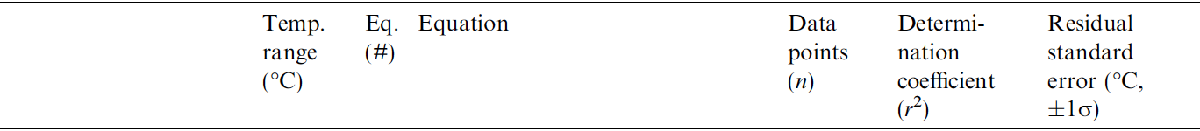

where

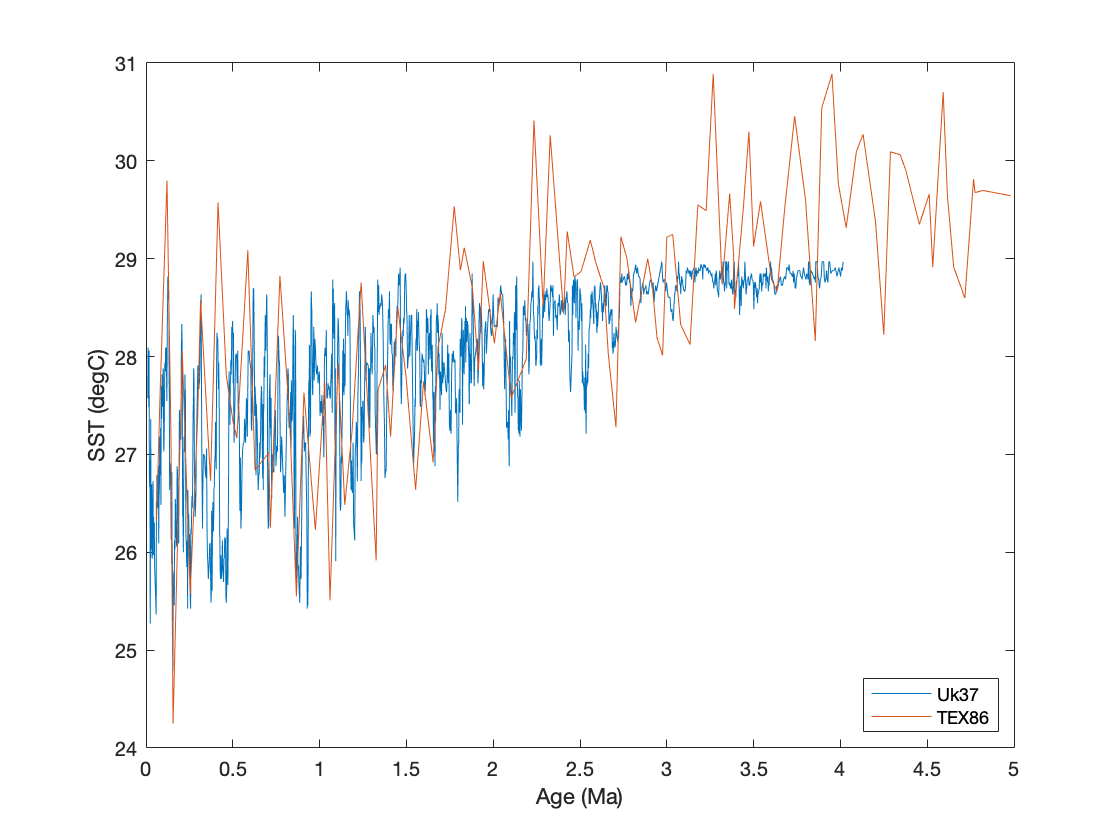

%Import the ODPsite data
load("SCS_tex.mat");

%Use the TEX86 formula to convert GDGT data to the TEX 86 index
SCS_tex.tex = (SCS_tex.GDGT2 + SCS_tex.GDGT3 + SCS_tex.cren)./(SCS_tex.GDGT1...
                + SCS_tex.GDGT2 + SCS_tex.GDGT3 + SCS_tex.cren);

%Use the core-top GDGT index-2 calibration model of Kim et al., 2010
SCS_tex.logtex = log10(SCS_tex.tex);
SCS_tex.SST = 68.4*SCS_tex.logtex + 38.6;

%Plot on the same figure as the Uk'37 reconstruction
figure(1)
plot(SCS_Li.age,SCS_Li.SST,SCS_tex.age,SCS_tex.SST)
xlabel('Age (Ma)')
ylabel('SST (degC)')
legend('Uk37','TEX86','location','southeast')

*What is the temperature range of the TEX86 reconstruction?*

max_tex = max(SCS_tex.SST);
min_tex = min(SCS_tex.SST);
fprintf(['The maximum and minimum estimates of the TEX86 reconstruction are %.2f and' ...
    ' %.2f degrees celsius respectively'], max_tex,min_tex)

The maximum and minimum estimates of the TEX86 reconstruction are 30.89 and 24.25 degrees celsius respectively

*Similar to Uk’37, TEX86 is an index that ranges from 0 to 1. What is the maximum TEX86 temperature that can be reconstructed using the core-top GDGT index-2 calibration model?*

%The limits of the TEX86 index are 0 and 1. Put these through the
%calibration model to see what they return.
texlims = [0 1];
texlims_log = log10(texlims);
texlims_sst = 68.4*texlims_log+38.6;
fprintf(['The maximum temperatrue using the core-top' ...
    'GDGT index-2 calibration model is %.2f degrees Celsius'],texlims_sst(2))

The maximum temperatrue using the core-topGDGT index-2 calibration model is 38.60 degrees Celsius

The GDGT index-2 calibration model for TEX86 returns a maximum SST of 38.60 degrees C, however this is greater than the maximum provided in the range in Kim et al., 2010 (which is 0 to 30 degrees C). This may be because the predictive ability of this model is poor above 30 degrees C.

## Question 3 - Combined Errors

Assessing error – propagating proxy errors (analytical and calibration).For palaeotemperature proxy estimates, there is analytical error associated with proxy signal you are measuring and also an error associated with the proxy-temperaturecalibration you choose to apply. Usually these errors of precision are probabilistic, e.g., expressed as a standard deviation. In order to assess the total error, palaeoclimatologists typically combine the errors in quadrature (error propagation) to preserve this probability.

i. Calculate the combined error (analytical and calibration) associated with the Uk’37SST estimates. The analytical (measurement) error is 0.006 Uk’37 units which equates to ±0.2 °C (Li et al., 2011). The calibration error (standard deviations of residuals) is provided in Fig. 8 of Müller et al. (1998).

%Define the analytical and calibration errors of the Uk'37 SST estimates
%and calculate the combined error.
anaerr_uk37 = 0.2;
calerr_uk37 = 1.5;
err_uk37 = sqrt(anaerr_uk37^2 + calerr_uk37^2);
fprintf('The combined error of the Uk37 reconstructions are %.2f degrees Celsius',err_uk37)

The combined error of the Uk37 reconstructions are 1.51 degrees Celsius

ii. Calculate the combined error associated with the TEX86 SST estimates. The reproducibility of the TEX86 values was determined to be ±0.014 (1 s.d.) (from 37 duplicate analyses, n=116), which is equivalent to ±0.61 °C. The calibration error (residual standard error) is provided in Table 1 of Kim et al. (2010).

%Define the analytical and calibration errors of the TEX86 SST
%reconstructions and calculate the combined error.
anaerr_tex = 0.61;
calerr_tex = 2.5;
err_tex = sqrt(anaerr_tex^2 + calerr_tex^2);
fprintf('The combined error of the TEX86 reconstructions are ±%.2f degrees Celsius',err_tex)

The combined error of the TEX86 reconstructions are ±2.57 degrees Celsius

iii. The two reconstructions perform similarly from the present until approximately 1.5Ma ago, showing similar longterm means and trends, with the TEX86 having greater variability, which concurs with it's greater error. Older than 1.5Ma, the two records show significant differences with the TEX86 reconstruction often reaching temperatures up to 1 degC higher than the Uk’37 reconstruction. This is likely due to Uk'37 reconstruction becoming less viable as it is near to it's upper limit.

## Question 4 - Trend Lines

i. Add a 10pt moving average to the plots for both the Uk'37 and TEX86 

%Find how many points are in each record
uknum = numel(SCS_Li.SST);
texnum = numel(SCS_tex.SST);
fprintf(['The Uk37 reconstruction has %d points and the TEX86 reconstruction' ...
    ' has %d points'],uknum,texnum)

The Uk37 reconstruction has 1587 points and the TEX86 reconstruction has 112 points

Not sure therefore how to do moving means that are comparable to each other. 10 points in the Uk'37 record will be much greater temporal resolution and therefore surely somewhat incomparable? I'll do one plot with a 10point average for both, and then one where I try make their temporal resolution similar.

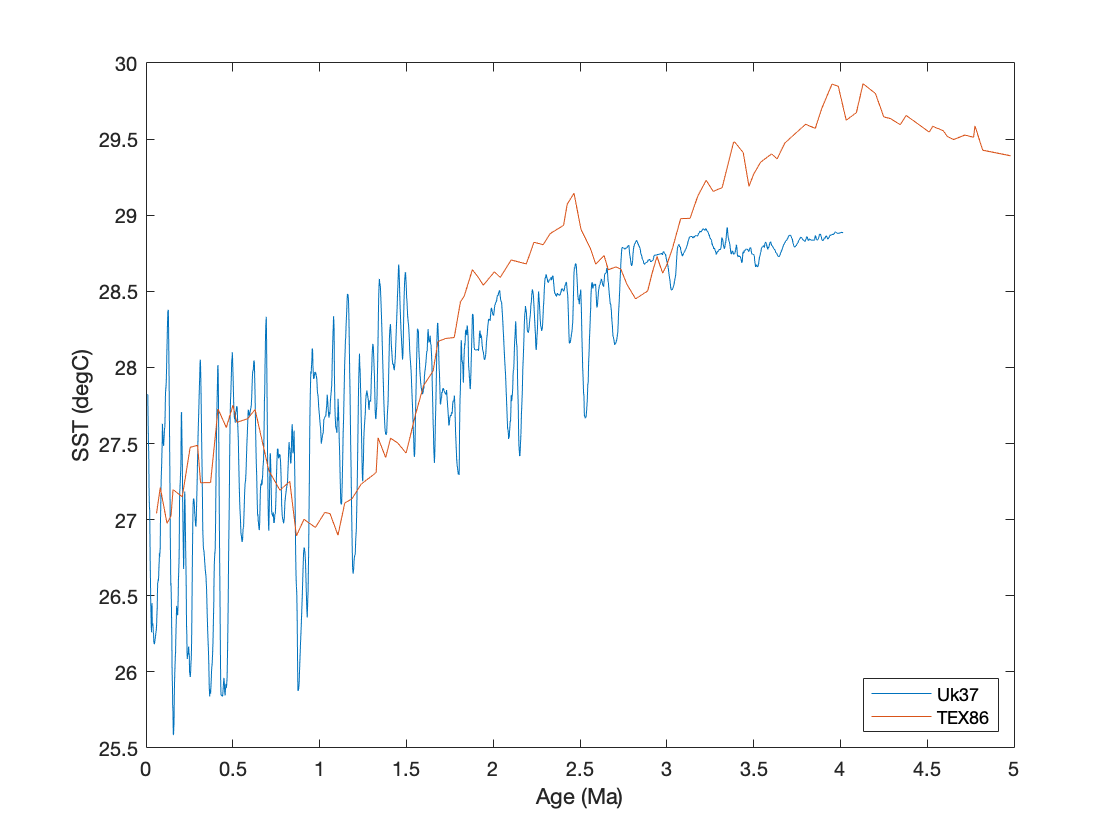

%Use the movmean function to create a 10-point moving average for both
%records and plot them
SCS_Li.SSTmov = movmean(SCS_Li.SST,10);
SCS_tex.SSTmov = movmean(SCS_tex.SST,10);
figure(2)
plot(SCS_Li.age,SCS_Li.SSTmov,SCS_tex.age,SCS_tex.SSTmov)
xlabel('Age (Ma)')
ylabel('SST (degC)')
legend('Uk37','TEX86','location','southeast')

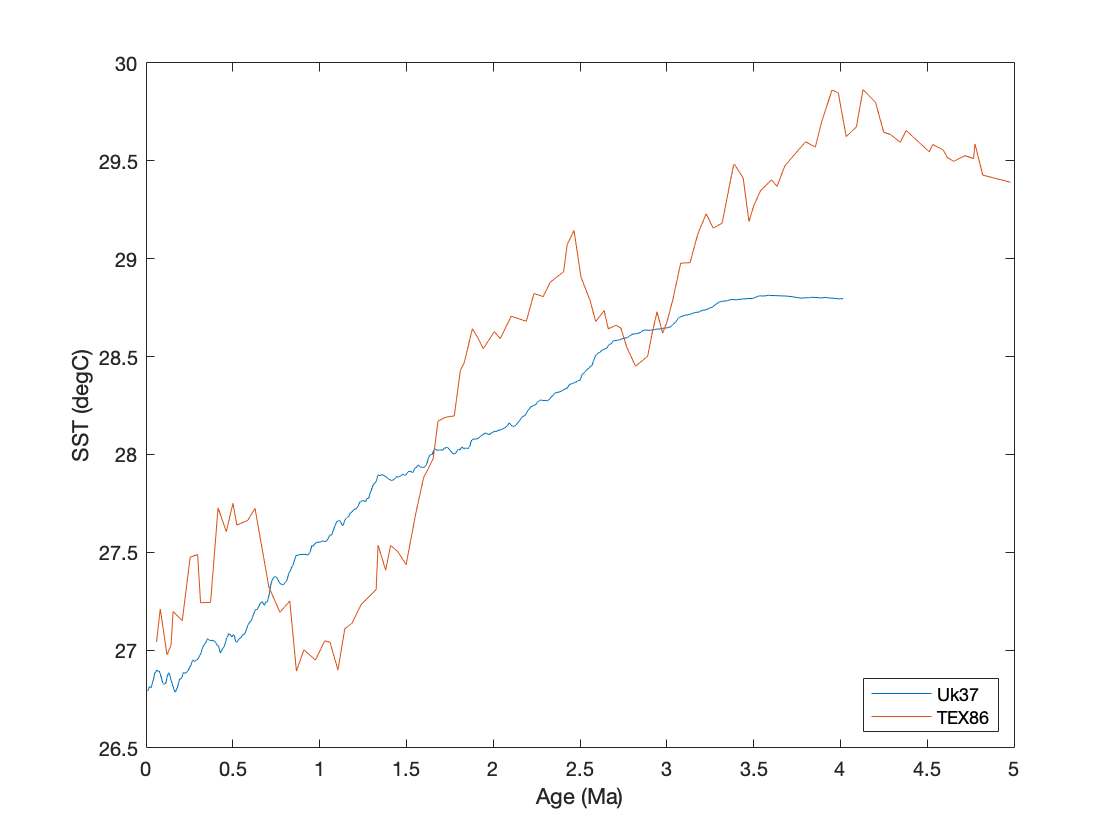

%Use the movmean function to create a moving average for both
%records such that their temporal resolutions are similar and plot them
uk_dt = mean(-SCS_Li.SST(1:end-1)+SCS_Li.SST(2:end));
tex_dt = mean(-SCS_tex.SST(1:end-1)+SCS_tex.SST(2:end));
dtratio = uk_dt/tex_dt;
n_tex = 10;
n_uk37 = round(n_tex/dtratio);
SCS_Li.SSTmov2 = movmean(SCS_Li.SST,n_uk37);
SCS_tex.SSTmov2 = movmean(SCS_tex.SST,n_tex);
figure(2)
plot(SCS_Li.age,SCS_Li.SSTmov2,SCS_tex.age,SCS_tex.SSTmov2)
xlabel('Age (Ma)')
ylabel('SST (degC)')
legend('Uk37','TEX86','location','southeast')

*ii. What might be driving some of the differences in the TEX86 versus Uk’37 SST estimates in the Pleistocene?*

The Uk'37 index is an alkenone-based proxy, whereas the TEX86 index is a GDGT-based proxy. Alkenones are produced by the phytoplankton class Prymnesiophycae, whereas GDGTs are produced by Thaumarchaeota, which oxidize ammonia to provide energy. There may be differences in the depth of the water column which these different organisms inhabited, which would lead to differences in the reconstructions. Furthermore, there may also be differences in exactly what periods of the year they record. The landmasses around the South China Sea show a strong monsoonal bi-annual seasonality. It may be, for example, that one group of organisms specifically blooms in the wet season, when there is high nutrient influx from the land, and therefore it's biomarker specifically records the SST of the wet season, whilst the other group of organisms is present year round, and therefore records the average annual SST.

## Question 5 - Mg/Ca

We can also reconstruct SSTs in the South China Sea using Mg/Ca ratios measured in planktic foraminifera.

i. Use the Mg/Ca data measured in planktic foraminifer species T. sacculifer to estimate SSTs at ODP 1143 (water depth 2700 m) for the past ~5 Myr. Convert Mg/Ca values to SSTs using the calibration equation of Dekens et al. (2002) for T. sacculifer in the Pacific:

What is the temperature range of the Mg/Ca-SST estimates?

%Import the Mg/Ca data
load('SCS_mgca')

%Apply the Dekens et al., 2002 temperature reconstruction to the Mg/Ca data
SCS_mgca.SST_dek = log(SCS_mgca.MgCa/0.37)/0.09+0.36*(2.7+SCS_mgca.Depth/1000)+2;

max_mgca = max(SCS_mgca.SST_dek);
min_mgca = min(SCS_mgca.SST_dek);
fprintf(['The maximum and minimum SST reconstructions from this Mg/Ca calibration are ' ...
    '%.2f and %.2f degrees Celsius respectively'], max_mgca,min_mgca)

The maximum and minimum SST reconstructions from this Mg/Ca calibration are 30.13 and 25.11 degrees Celsius respectively

ii.Plot these Mg/Ca-SST estimates on the same graph as the Uk’37 and TEX86 data. How do the Mg/Ca-SST estimates compare with the Uk’37- and TEX86-SST reconstructions for this site during the Pliocene and Pleistocene?

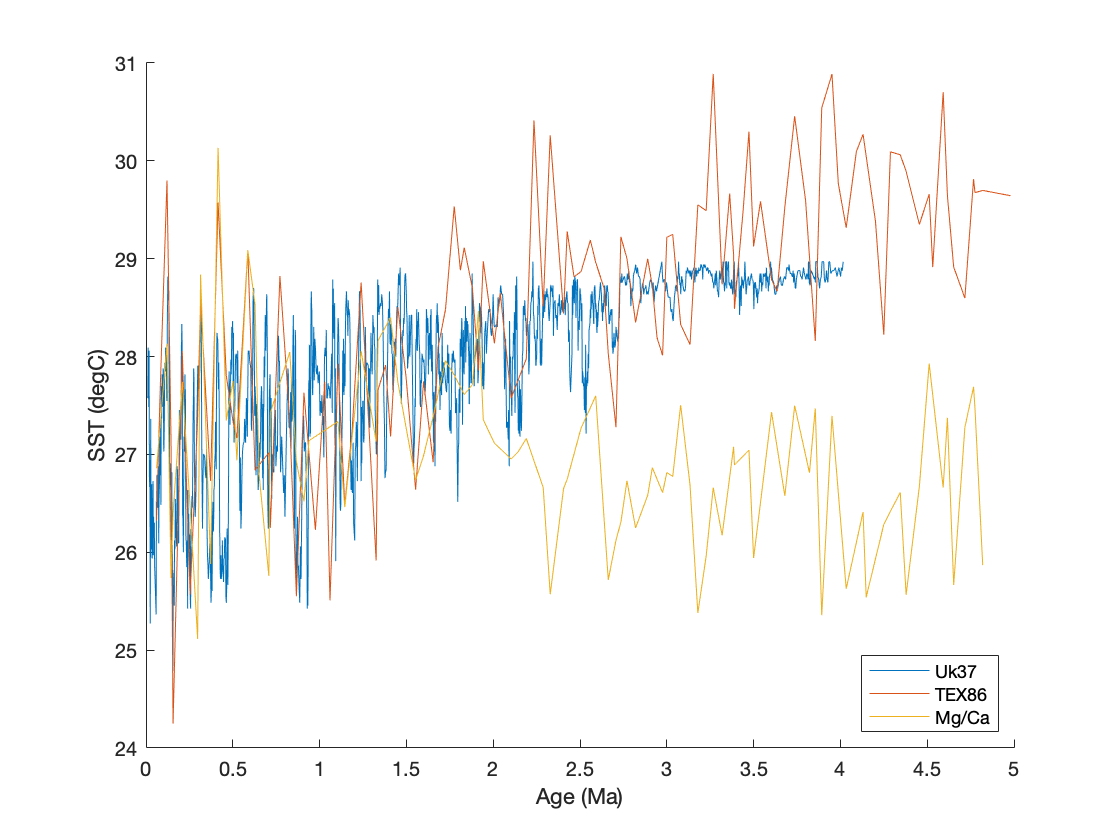

figure(3)
clf

hold on
ukplot = plot(SCS_Li.age,SCS_Li.SST,'LineStyle','-');
texplot = plot(SCS_tex.age,SCS_tex.SST,'LineStyle','-');
mgcaplot = plot(SCS_mgca.Age,SCS_mgca.SST_dek);


xlabel('Age (Ma)')
ylabel('SST (degC)')
legend('Uk37','TEX86','Mg/Ca','location','southeast')

The Mg/Ca SST reconstruction produces a similar mean to the Uk'37 and TEX86 reconstructions from 0 to 1.5Ma, however it then diverges significantly to provide much lower estimates earlier than 2Ma. The variability is similar to the TEX86 reconstruction throughout however.

*iii.The ratio of Mg/Ca in seawater (Mg/Casw) is known to vary on timescales >1 Myr. This is understood to effect the ratio of Mg/Ca incorporated into planktic foraminiferal calcite. Various corrections have been developed to correct foraminiferal Mg/Ca values for secular variations in Mg/Ca in seawater on geological timescales. Plot the corrected Mg/Ca-SST estimates (given in the Excel file – FD06 linear) on the graph. How do the Mg/Casw-corrected Mg/Ca-SST estimates compare with the Uk’ 37- and TEX86-SST reconstructions for this site during the Pliocene and Pleistocene?*

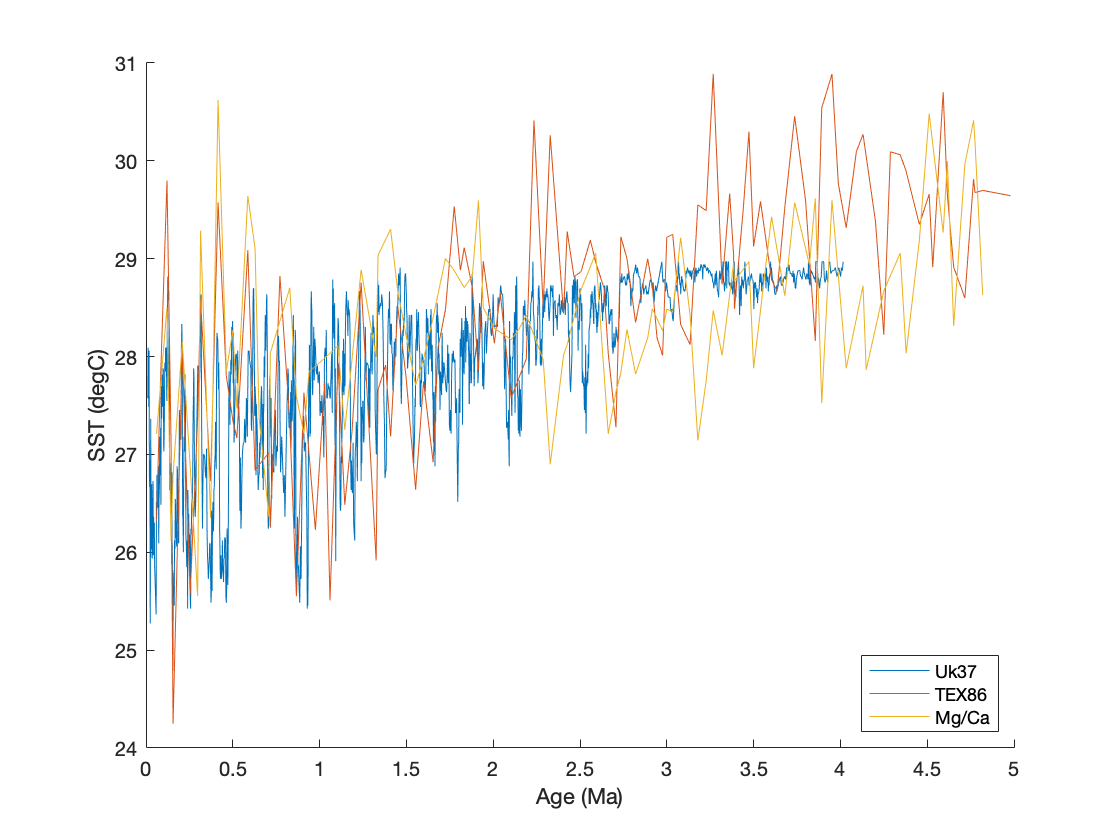

figure(4)
clf

hold on
ukplot = plot(SCS_Li.age,SCS_Li.SST,'LineStyle','-');
texplot = plot(SCS_tex.age,SCS_tex.SST,'LineStyle','-');
mgcaplot = plot(SCS_mgca.Age,SCS_mgca.SST_lin);


xlabel('Age (Ma)')
ylabel('SST (degC)')
legend('Uk37','TEX86','Mg/Ca','location','southeast')

The Mg/Casw-corrected Mg/Ca SST reconstructions display much greater similarity to the Uk'37 and TEX86 reconstructions than the non-sw-corrected Mg/Ca SST reconstruction, particularly earlier than 1.5Ma. It shows a similar decreasing trend throughout the last 5Ma, with similar vairability to the TEX86 reconstruction throughout.

## Question 6 - mid-Piacenzian warm period

The model reconstructions in Fig. A (first page of this handout) are SST anomalies forthe mid-Piacenzian warm period–preindustrial.

i. Calculate the mean TEX86-SST during the mid-Piacenzian warm period (3.264–3.025 Ma) and then calculate ΔSST, mid-Piacenzian warm period–preindustrial. For the “preindustrial” estimate use the top most sample from the core. How old is this sample/which Epoch is it from?

%Calculate the mean TEX86-SST across the mid-P
indx = SCS_tex.age>= 3.025 & SCS_tex.age<= 3.264;
midP_texmean = mean(SCS_tex.SST(indx));
fprintf(['The mean mid-Piacenzian warm period SST from the TEX86 reconstruction' ...
    ' is %.2f degrees C'],midP_texmean)

The mean mid-Piacenzian warm period SST from the TEX86 reconstruction is 28.95 degrees C

%Calculate deltaSST from the mid-P to the preindustrial.
midPtopre_tex = midP_texmean-SCS_tex.SST(1);
fprintf(['The difference between the mean of the mid-Piacenzian warm period and the' ...
    ' preindustrial is %.2f degrees C'],midPtopre_tex)

The difference between the mean of the mid-Piacenzian warm period and the preindustrial is 2.62 degrees C

fprintf('The top most sample from the TEX record dates to %.1f ka',SCS_tex.age(1)*1000)

The top most sample from the TEX record dates to 60.7 ka

The top most sample from the TEX record dates to 60.7 ka, which means it is older than the Holocene (starting around 11.7ka) and is actually from the Late Pleistocene, therefore not representing the preindustrial terribly well.

*ii. Now calculate ΔSST again using the mean TEX86-SST during the mid-Piacenzian warm period (MPWP, 3.264–3.025 Ma), however, this time for the “preindustrial” estimate use the mean of Holocene Uk’37-SST estimates from the same site.*

%Taking the Holocene as being from present to 11,700ya (the beginning of
%the Greenlandian), calculate the mean Uk'37 SST for the holocene
indx = SCS_Li.age>= 0 & SCS_Li.age<=11700/1e6;
hol_ukmean = mean(SCS_Li.SST(indx));
midPtohol = midP_texmean - hol_ukmean;
fprintf('The change in SST from mid-Piacenzian to preindustrial is %.2f degrees C',midPtohol)

The change in SST from mid-Piacenzian to preindustrial is 1.37 degrees C

SCS_Li.age(1:5)

ans =     0.0104
    0.0122
    0.0140
    0.0159
    0.0177


*iii. What are the pros and cons of these two choices of estimate for the “preindustrial”?*

The topmost value from the TEX86 dataset dates to 60.7ka, over 60kya before the preindustrial, whereas the topmost value from the Uk'37 dataset dates to 10.4ka, and therefore is within the Holocene, better representing the preindustrial. Whilst the Uk'37 choice is calculated by averaging all Holocene datapoints, there is actually only one datapoint within the Holocene from that record, and therefore they are both actually calculated from a singular datapoint. We know, however, that the error of the Uk'37 reconstruction is lower than the TEX reconstruction error, and that the recent portion of Uk'37 reconstruction doesn't suffer from the same boundary problem as that past 2.5Ma, making the Uk'37 data a good candidate for this calculation.

*iv. How do the two ΔSST estimates compare with the model reconstructions in Fig.A? Based on the available proxy data and model predictions, what would be your overall conclusion about MPWP temperatures in the western Pacific relative to preindustrial/the Holocene.*

The deltaSST from the model reconstructions range from -0.5 to 3 degrees C, but clustering around 0.8 to 2 degrees C. The second estimate, using the Uk'37 values for the pre-industrial provides a deltaSST of 1.37 degrees C, which is in accordance with the 0.8 to 2 degrees C range that the model reconstructions suggest. Overall, I would conclude that the MPWP SSTs were 1.4 ± 0.6 degrees C warmer than the Holocene.

*v. In this exercise we have reconstructed warm pool temperatures using a single core site from the southern South China Sea. The South China Sea is at the edge of the warm pool. So is it the best test of past warm pool temperatures? Why not?*

Being at the edge of the warm pool, it may not represent the greatest warming of the warm pool. A better test might use more core sites from different locations, or one from a location that is expected (by modelling for example) to be the epicentre of the warming.

## Question 7 - Overview

*Summarise the strengths and weaknesses of Uk’37 and TEX86 as SST proxies. How do these compare with the benefits and challenges of planktic foraminifera Mg/Ca palaeothermometry? Write your answer as bullet points.*